% Plot graphs
Plot = false;

% Determine where your m-file's folder is
folder = fileparts(which("opt_problem.mlx"));
% Add that folder plus all subfolders to the path
addpath(genpath(folder));

GFDM parameters

gfdm = struct;
gfdm.K = 13; % Subcarriers
gfdm.M = 7; % Subsymbols

gfdm.K_on = 6;
gfdm.M_on = 6;
k0 = 11;
m0 = 1;

gfdm.CP = 0; % CP length

B = 82; % Bandwidth
SEM_cnannel = 80;

Es = 1; % Symbol energy

gfdm = GFDM_init(gfdm);

D = gfdm.D;
D_prime = gfdm.D_prime;

Normalized frequency $f$ and normalized frequency interval $\Delta f$

delta_f = 0.001;     % Normalized frequency: f = F/Fs = F/2B = F*Ts
f_range_end = 0.5;   % rc filter limit

% f_range_end should be divisible by delta_f
if mod(f_range_end,f_range_end)
    msg = 'normalized frequency sampling interval delta_f can not equally spaces f_range';
    error(msg);
end

f_range = [0 f_range_end];
f = -f_range(2):delta_f:f_range(2);

Interpolation filter $P(f)$

P = rc_filter(delta_f, f_range, 0.1);

Optimization problem & Dottorro iterative algorithm


$$\mathbf{S}=\mathbf{g}\mathbf{g}^H$$


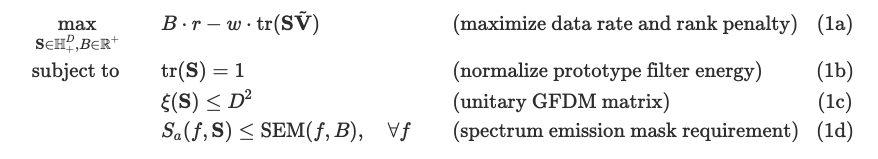

while 1 % B increment loop
    B

    % Set used K and M indeces
    k_set_temp = circshift(0:gfdm.K-1, - k0);
    k_set = k_set_temp(1:gfdm.K_on);
    m_set_temp = circshift(0:gfdm.M-1, - m0);
    m_set = m_set_temp(1:gfdm.M_on);

    % Initialize values
    s_2 = 1;
    w = 0.1;  % Rank 1 penalty
    V_tilde = zeros(D);
    problem_counter = 1;

    % Dottorro loop: solve the optimization problem until the second largest
    % singular value is small enough
    dottorro_start = tic;
    while abs(s_2) > 10^-6
        problem_start = tic;
        cvx_begin sdp quiet
        variable S(D, D) hermitian nonnegative semidefinite
        expression psd_temp(length(P), 1)

        % SEM
        mask_ac_dB = ac(delta_f, f_range, B, SEM_cnannel);
        mask_ac_linear = db2pow(mask_ac_dB);

        % PSD
        psd = (P.^2) .* PSD_S(S, f_range, psd_temp, gfdm.K, gfdm.M, k_set, m_set, gfdm.CP, delta_f, Es);

        minimize -B + w*trace(S * V_tilde)     % (1a)
        subject to
        trace(S) == 1;                       % (1b)
        nep_S(S, gfdm.K, gfdm.M) <= D^2;     % (1c)
        psd <= mask_ac_linear;               % (1d)

        cvx_end
        fprintf('Problem time: %s\n', duration([0, 0, toc(problem_start)]));

$\tilde{\mathbf{V}}=\mathbf{U}\mathbf{U}^H, \mathbf{U} $ is $\mathbf{Q}$ with first column removed.

$\tilde{\mathbf{V}}$represents the (D-1)-dimensional space orthogonal to the principal eigenvector of $\mathbf{S}$ in the previous iteration.

        try
            [U_svd, S_svd, ~] = svd(S);
        catch ME
            fprintf('B = %d is INFEASIBLE.\n', B);
            fprintf('Dottorro time: %s\n', duration([0, 0, toc(dottorro_start)]));
            fprintf('===============================\n');
            break;
        end

        % Break the B increment loop if infeasible
        if isnan(S_svd(1, 1))
            fprintf('B = %d is INFEASIBLE.\n', B);
            fprintf('Dottorro time: %s\n', duration([0, 0, toc(dottorro_start)]));
            fprintf('===============================\n');
            break;
        end

        s_2 = S_svd(2, 2);
        fprintf('%d.s_2 = %f\n\n', problem_counter, s_2);

        U = U_svd(:, 2:end);
        V_tilde = U*U';

        problem_counter = problem_counter + 1;

Plot $S_a(f, \mathbf{S})$ and SEM

        if Plot == 1
            g = U_svd(:, 1) .* sqrt(S(1, 1));
            G = g2chaG(g, gfdm.K, gfdm.M);
            S_a = PSD(G, B, f_range, gfdm.K, gfdm.M, k_set, m_set, gfdm.CP, delta_f, Es);
            plot_PSD((P.^2) .* S_a, mask_ac_linear, f_range);
        end
    end

    if isnan(S_svd(1, 1))
        break;
    end

    if abs(s_2) < 10^-6
        S_solved = S;
        fprintf('%B = %d is feasible.\n', B);
        fprintf('Dottorro time: %s\n', duration([0, 0, toc(dottorro_start)]));
        fprintf('===============================\n');

Obtain the GFDM prototype filter $\mathbf{g}$

        g = U_svd(:, 1) .* sqrt(S(1, 1));
        G = g2chaG(g, gfdm.K, gfdm.M);
        S_a_S = PSD_S(S, f_range, psd_temp, gfdm.K, gfdm.M, k_set, m_set, gfdm.CP, delta_f, Es);

        if Plot == 1
            plot_PSD((P.^2) .* S_a_S, mask_ac_linear, f_range);
        end
    end

    B = B+1;
end

B = 82

Problem time: 00:02:02


1.s_2 = 0.096973



Problem time: 00:02:36


2.s_2 = 0.053472



Problem time: 00:03:43


3.s_2 = 0.053555



Problem time: 00:02:34


4.s_2 = 0.053252



Problem time: 00:03:07


5.s_2 = 0.053459



Problem time: 00:03:41


6.s_2 = 0.053468



Problem time: 00:02:35


7.s_2 = 0.052925



Problem time: 00:03:27


8.s_2 = 0.018013



Problem time: 00:02:56


9.s_2 = 0.000007



Problem time: 00:04:20


10.s_2 = 0.000000



Dottorro time: 00:31:06


B = 83

Problem time: 00:02:10


1.s_2 = 0.121509



Problem time: 00:02:32


2.s_2 = 0.056561



Problem time: 00:02:24


3.s_2 = 0.056043



Problem time: 00:03:06


4.s_2 = 0.056032



Problem time: 00:03:16


5.s_2 = 0.056267



Problem time: 00:02:23


6.s_2 = 0.055941



Problem time: 00:03:35


7.s_2 = 0.056131




%Max bandwidth
B=B-1   % -1 since the last trial is infeasible

 
mask_ac_dB = ac(delta_f, f_range, B, SEM_cnannel);
mask_ac_linear = db2pow(mask_ac_dB);
psd_temp = zeros(size(P));
S_a = PSD(G, B, f_range, gfdm.K, gfdm.M, k_set, m_set, gfdm.CP, delta_f, Es);
% S_a_S = PSD_S(S_solved, f_range, psd_temp, gfdm.K, gfdm.M, k_set, m_set, gfdm.CP, delta_f, Es);
plot_PSD((P.^2) .* S_a, mask_ac_linear, f_range);
text(-0.2, -50, ['$K_{on}$[ ' regexprep(num2str(k_set),'\s+', ',') ' ]'], 'interpreter','latex');
text(-0.2, -55, ['$M_{on}$[ ' regexprep(num2str(m_set),'\s+', ',') ' ]'], 'interpreter','latex');